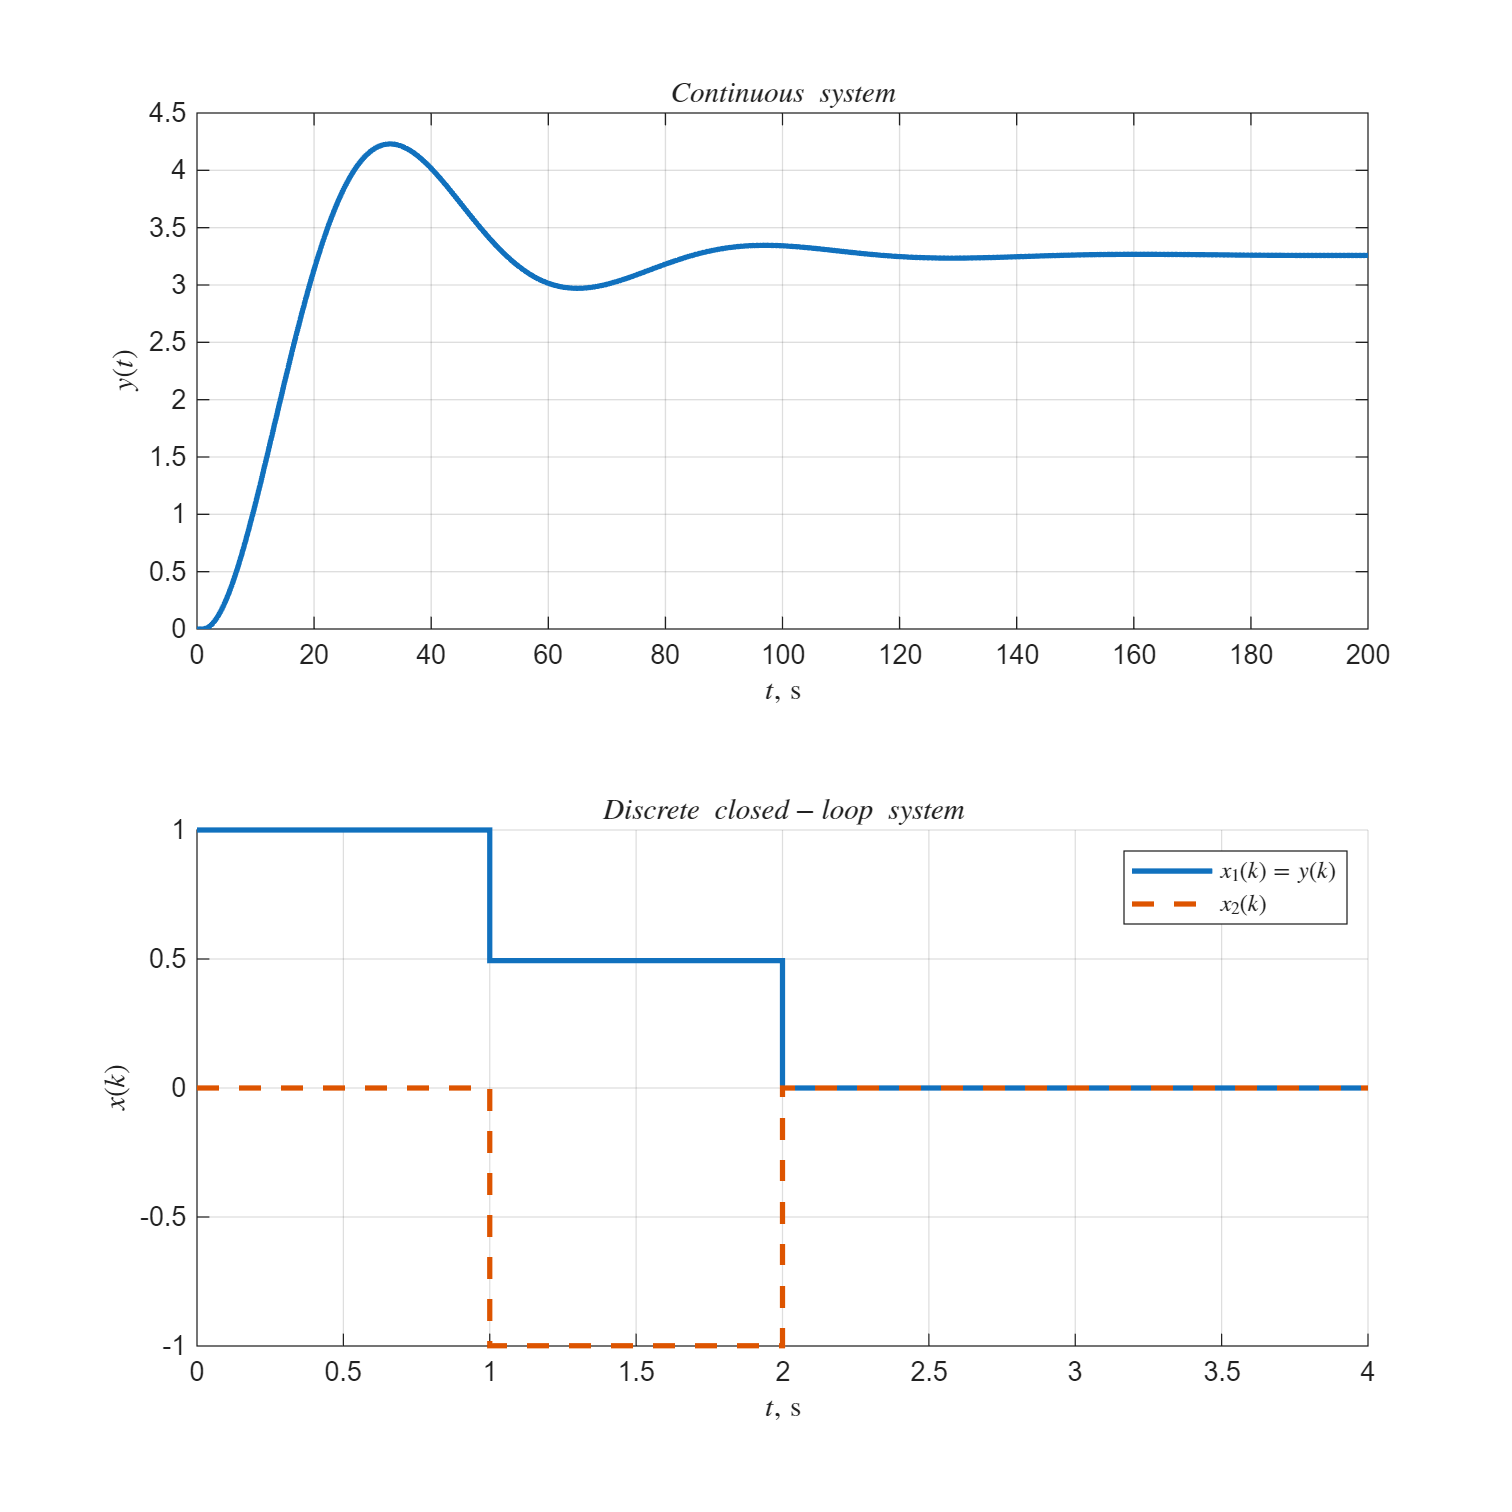

k1 = 3.26;
k2 = 1;
T1 = 9.5;
ksi = 0.36;
a01 = 1;
a02 = 1;
T = 1;

Ac = [0 1; -a01*a02/T1^2 -2*ksi/T1];
Bc = [0; k1*k2/T1^2];

sys = c2d(ss(Ac, Bc, [1 0], 0), T, "zoh");

A = sys.A;
B = sys.B;
C = eye(2);
D = zeros(2,1);

rankU = rank([B A*B]);
rankO = rank([C(1,:); C(1,:)*A]);

Gamma = [0 1; 0 0];
H = [1 0];

M = sylvester(-A, Gamma, -B*H);
K = H/M;
F = A - B*K;
eigF = eig(F);

simtime = 200;
out = sim("lab2.slx", simtime);

y1 = out.y1.Data;
t1 = out.y1.Time;

x = out.y2.Data;
t2 = out.y2.Time;

f = figure;
f.Position = [100 100 900 900];

subplot(2,1,1);
plot(t1, y1, LineWidth=2);
grid on;
title("$Continuous\ system$", Interpreter="latex");
xlabel("$t,\;\mathrm{s}$", Interpreter="latex");
ylabel("$y(t)$", Interpreter="latex");

subplot(2,1,2);
hold on;
stairs(t2, x(:,1), LineWidth=2);
stairs(t2, x(:,2), LineStyle="--", LineWidth=2);
hold off;

legend({"$x_1(k)=y(k)$", "$x_2(k)$"}, Interpreter="latex");
grid on;
xlim([0 4]);
title("$Discrete\ closed-loop\ system$", Interpreter="latex");
xlabel("$t,\;\mathrm{s}$", Interpreter="latex");
ylabel("$x(k)$", Interpreter="latex");

folder = "C:\Users\Nickolay\Desktop\ITMO-courses\7_term\Discrete_control_systems\lab2\tex\images\";
exportgraphics(f, fullfile(folder, "task1_stabilization.png"), Resolution=600);

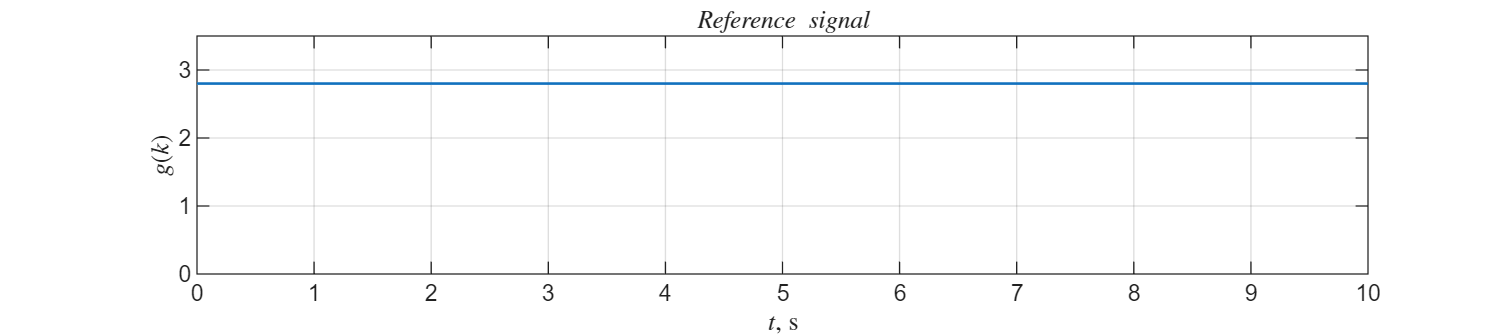

C0 = [1 0];

Ab = [1 -C0; zeros(2,1) A];
Bb = [0; B];

rankU = rank([Bb Ab*Bb Ab^2*Bb]);

Gamma = [0 1 0; 0 0 1; 0 0 0];
H = [1 0 0];

M = sylvester(-Ab, Gamma, -Bb*H);
Kb = H/M;

Keta = -Kb(1);
kappa1 = Kb(2);
kappa2 = Kb(3);

F = Ab - Bb*Kb;
eigF = eig(F);

simtime = 10;
out = sim("lab22.slx", simtime);

g = out.g.Data;
tg = out.g.Time;

y = out.y.Data;
e = out.e.Data;
t = out.y.Time;

f = figure;
f.Position = [100 100 900 200];

stairs(tg, g, LineWidth=1);
grid on;
ylim([0 3.5]);

title("$Reference\ signal$", Interpreter="latex");
xlabel("$t,\;\mathrm{s}$", Interpreter="latex");
ylabel("$g(k)$", Interpreter="latex");

exportgraphics(f, fullfile(folder, "task2_generator.png"), Resolution=600);

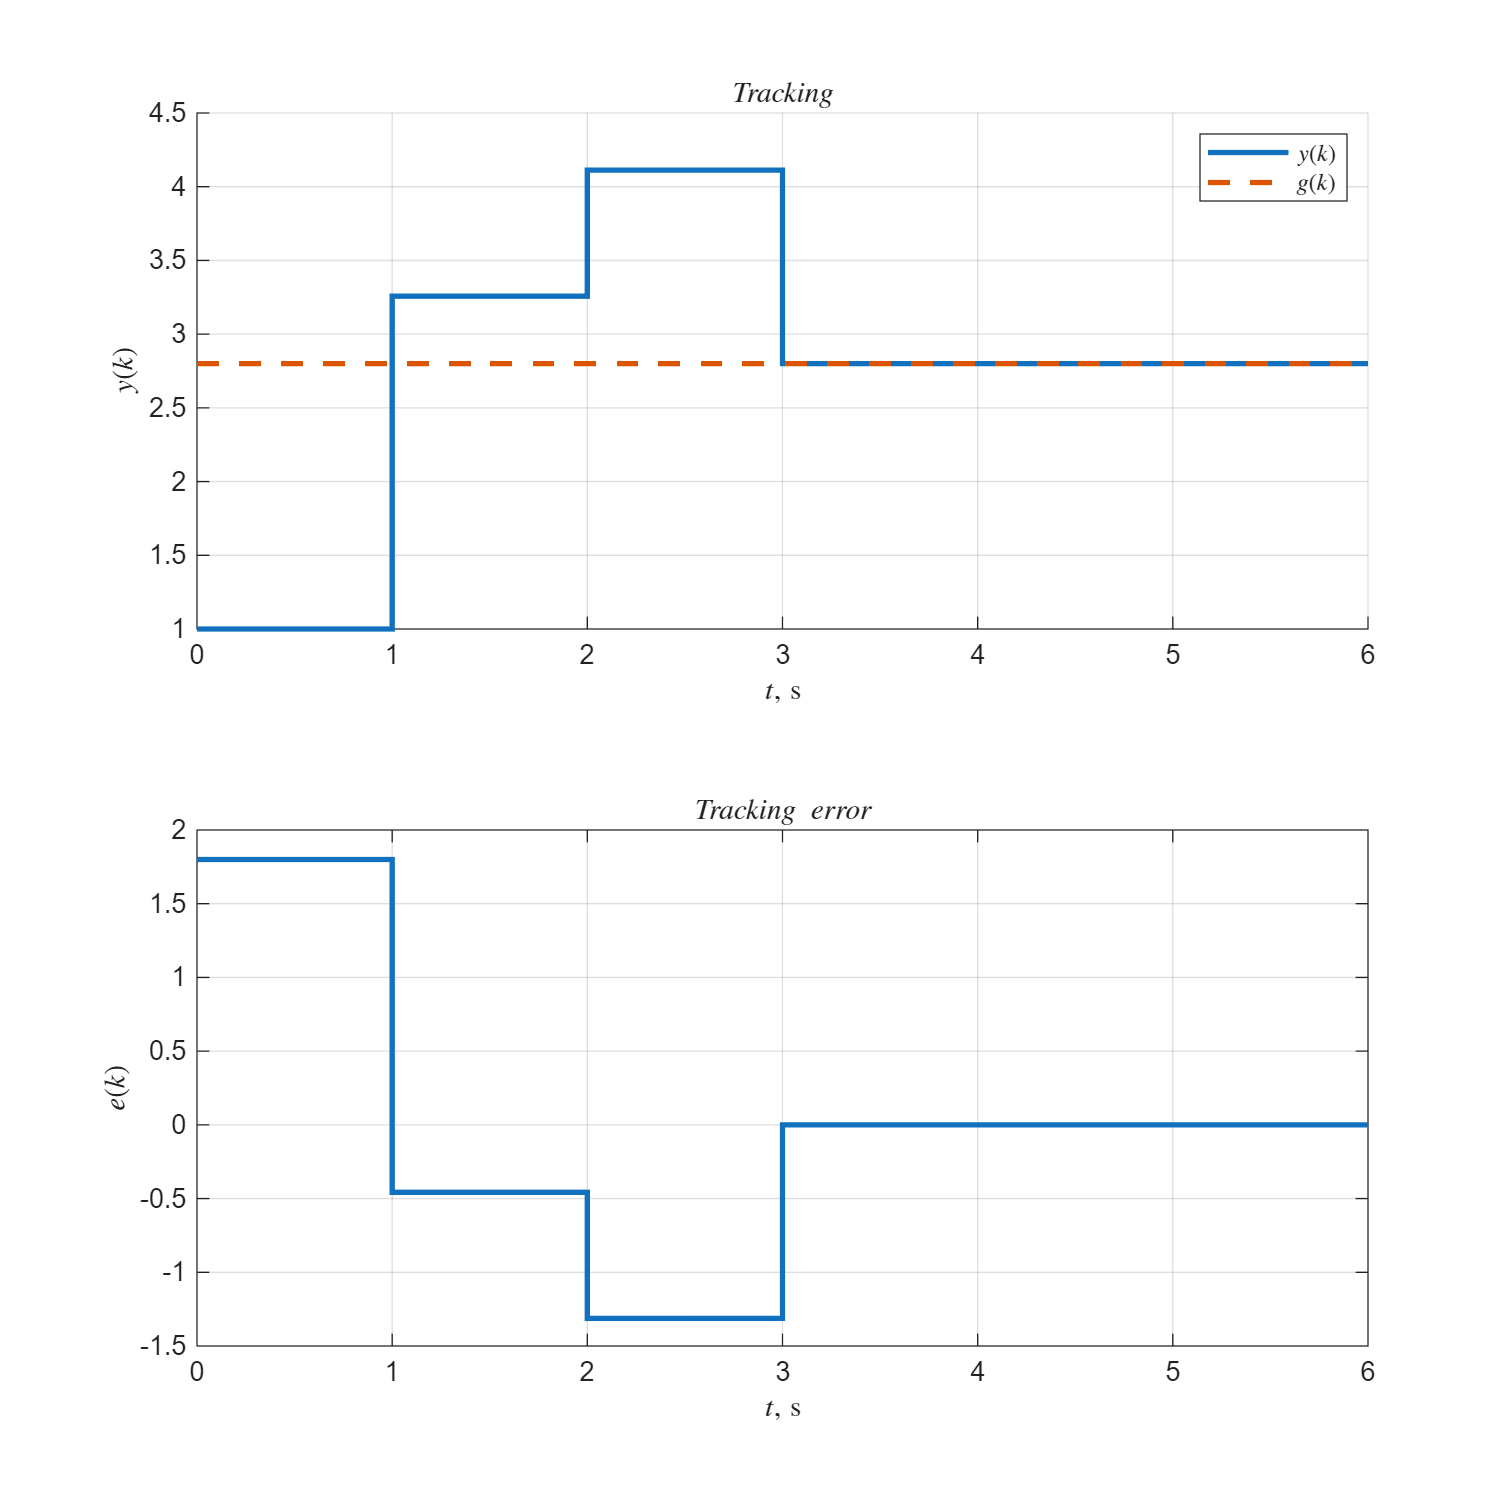


f = figure;
f.Position = [100 100 900 900];

subplot(2,1,1);
hold on;
stairs(t, y, LineWidth=2);
stairs(tg, g, LineStyle="--", LineWidth=2);
hold off;

legend({"$y(k)$", "$g(k)$"}, Interpreter="latex");
grid on;
xlim([0 6]);
title("$Tracking$", Interpreter="latex");
xlabel("$t,\;\mathrm{s}$", Interpreter="latex");
ylabel("$y(k)$", Interpreter="latex");

subplot(2,1,2);
stairs(t, e, LineWidth=2);
grid on;
xlim([0 6]);
title("$Tracking\ error$", Interpreter="latex");
xlabel("$t,\;\mathrm{s}$", Interpreter="latex");
ylabel("$e(k)$", Interpreter="latex");

exportgraphics(f, fullfile(folder, "task2_tracking.png"), Resolution=600);

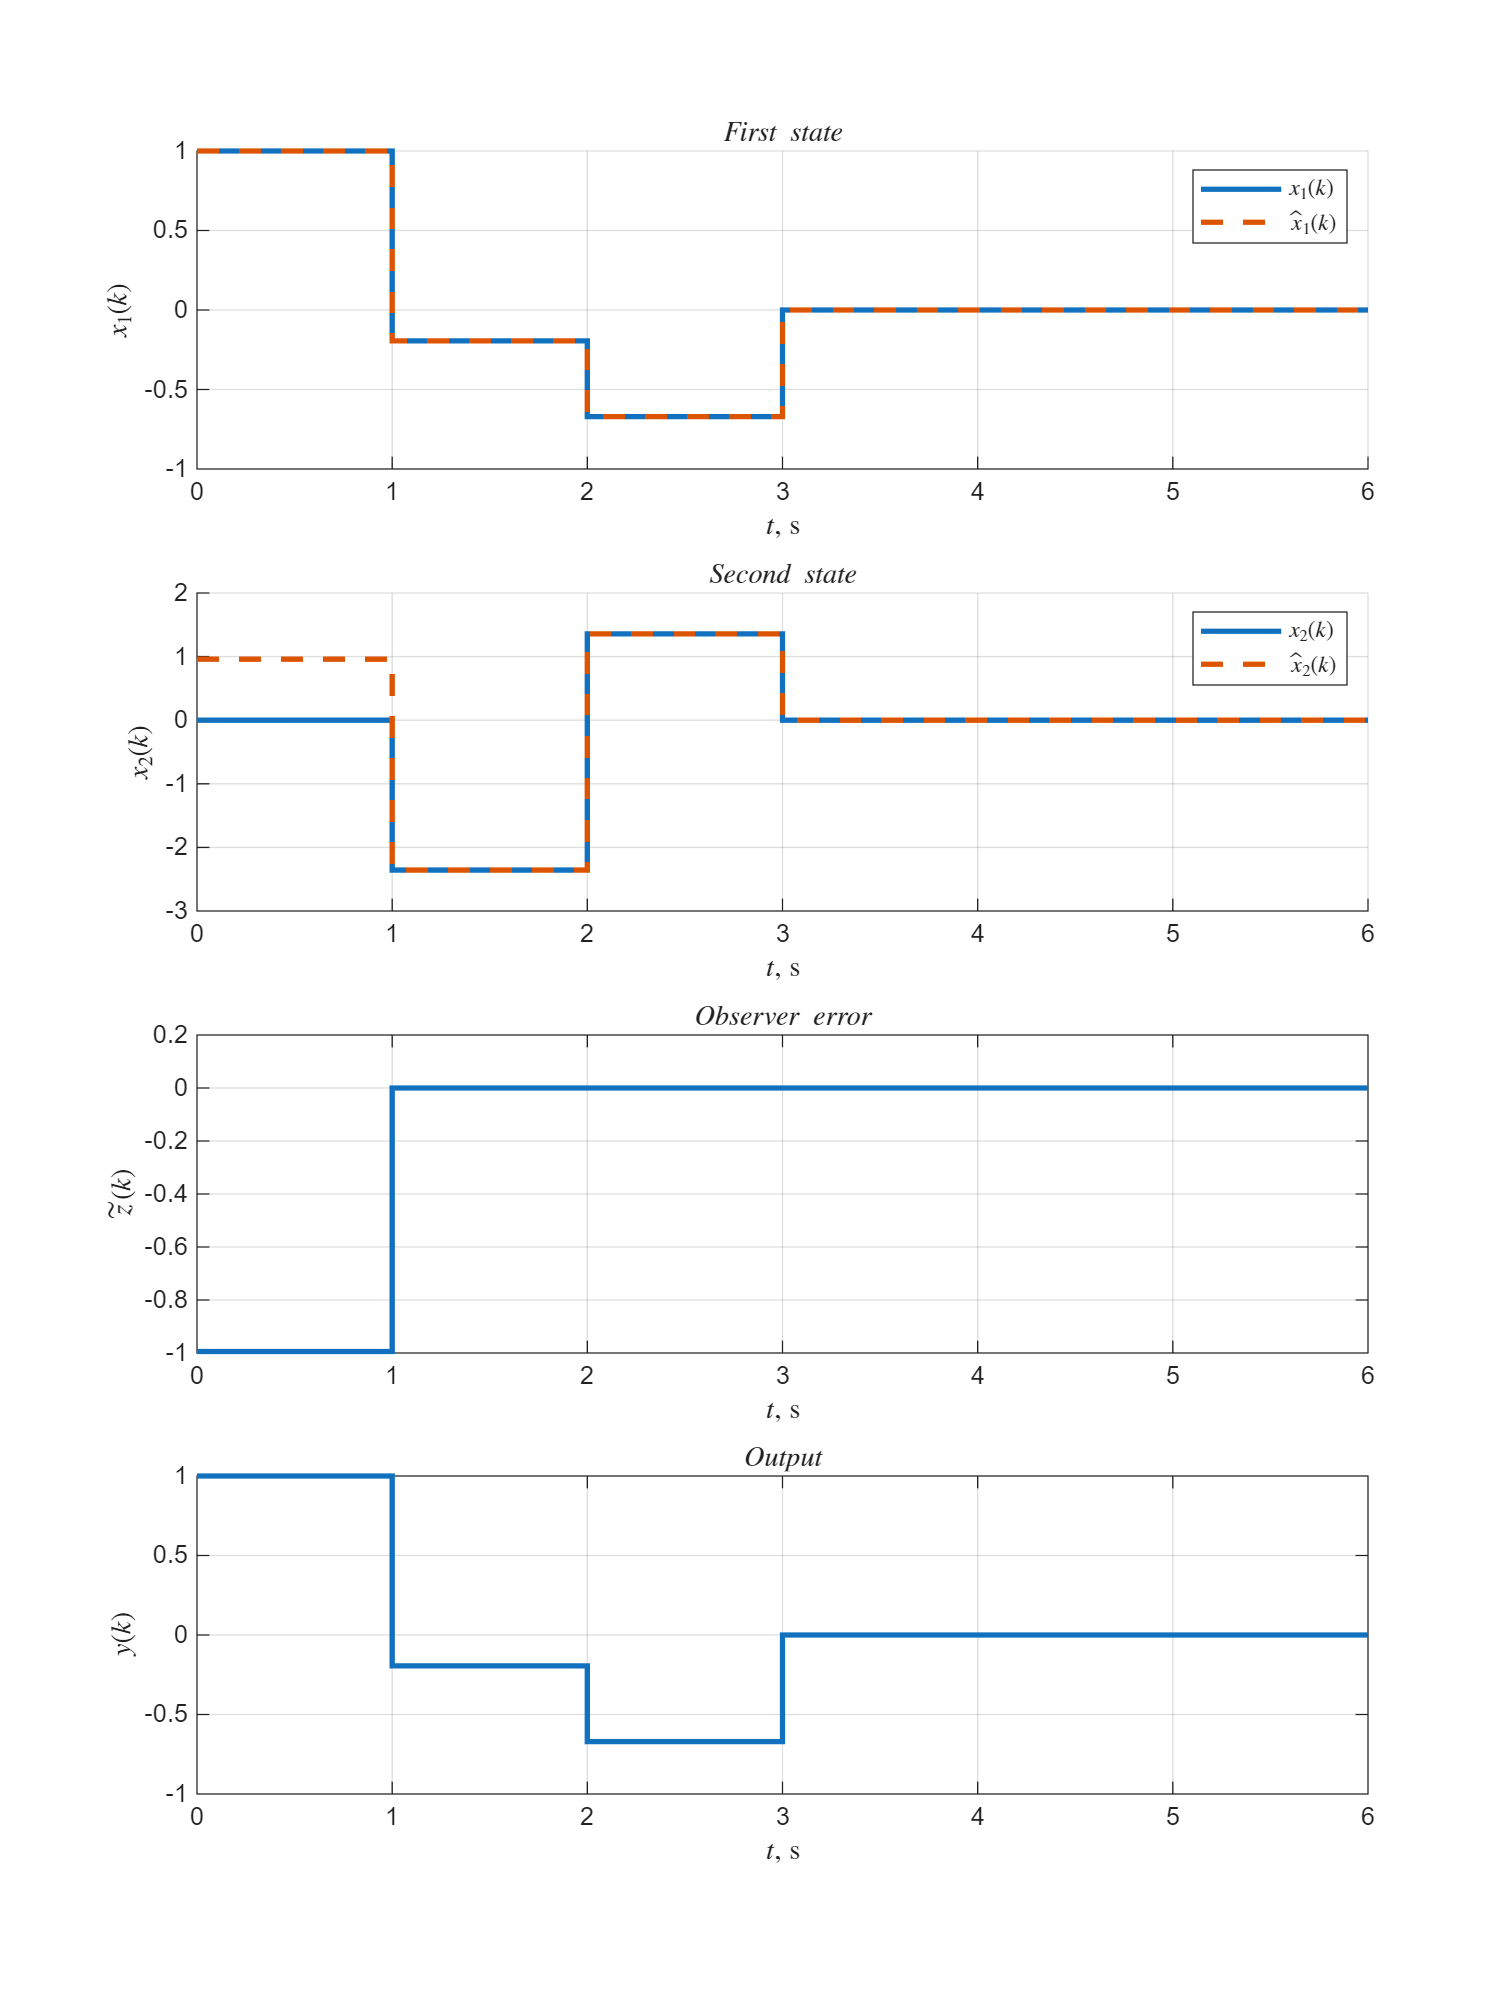


Mn = C0/A;
mb = Mn*B;
R = inv([C0; Mn]);

EDs = K*R;
Es = EDs(1);
Ds = EDs(2);

EDt = [kappa1 kappa2]*R;
Et = EDt(1);
Dt = EDt(2);
out = sim("lab23.slx", simtime);

x = out.obs_sx.Data;
z = out.obs_sz.Data;
t = out.obs_sx.Time;

xh = [x(:,1) z]*R';
dz = z - x*Mn';

f = figure;
f.Position = [100 100 900 1200];

subplot(4,1,1);
hold on;
stairs(t, x(:,1), LineWidth=2);
stairs(t, xh(:,1), LineStyle="--", LineWidth=2);
hold off;

legend({"$x_1(k)$", "$\hat{x}_1(k)$"}, Interpreter="latex");
grid on;
xlim([0 6]);
title("$First\ state$", Interpreter="latex");
xlabel("$t,\;\mathrm{s}$", Interpreter="latex");
ylabel("$x_1(k)$", Interpreter="latex");

subplot(4,1,2);
hold on;
stairs(t, x(:,2), LineWidth=2);
stairs(t, xh(:,2), LineStyle="--", LineWidth=2);
hold off;

legend({"$x_2(k)$", "$\hat{x}_2(k)$"}, Interpreter="latex");
grid on;
xlim([0 6]);
title("$Second\ state$", Interpreter="latex");
xlabel("$t,\;\mathrm{s}$", Interpreter="latex");
ylabel("$x_2(k)$", Interpreter="latex");

subplot(4,1,3);
stairs(t, dz, LineWidth=2);
grid on;
xlim([0 6]);
title("$Observer\ error$", Interpreter="latex");
xlabel("$t,\;\mathrm{s}$", Interpreter="latex");
ylabel("$\tilde{z}(k)$", Interpreter="latex");

subplot(4,1,4);
stairs(t, x(:,1), LineWidth=2);
grid on;
xlim([0 6]);
title("$Output$", Interpreter="latex");
xlabel("$t,\;\mathrm{s}$", Interpreter="latex");
ylabel("$y(k)$", Interpreter="latex");

exportgraphics(f, fullfile(folder, "task3_stabilization_observer.png"), Resolution=600);

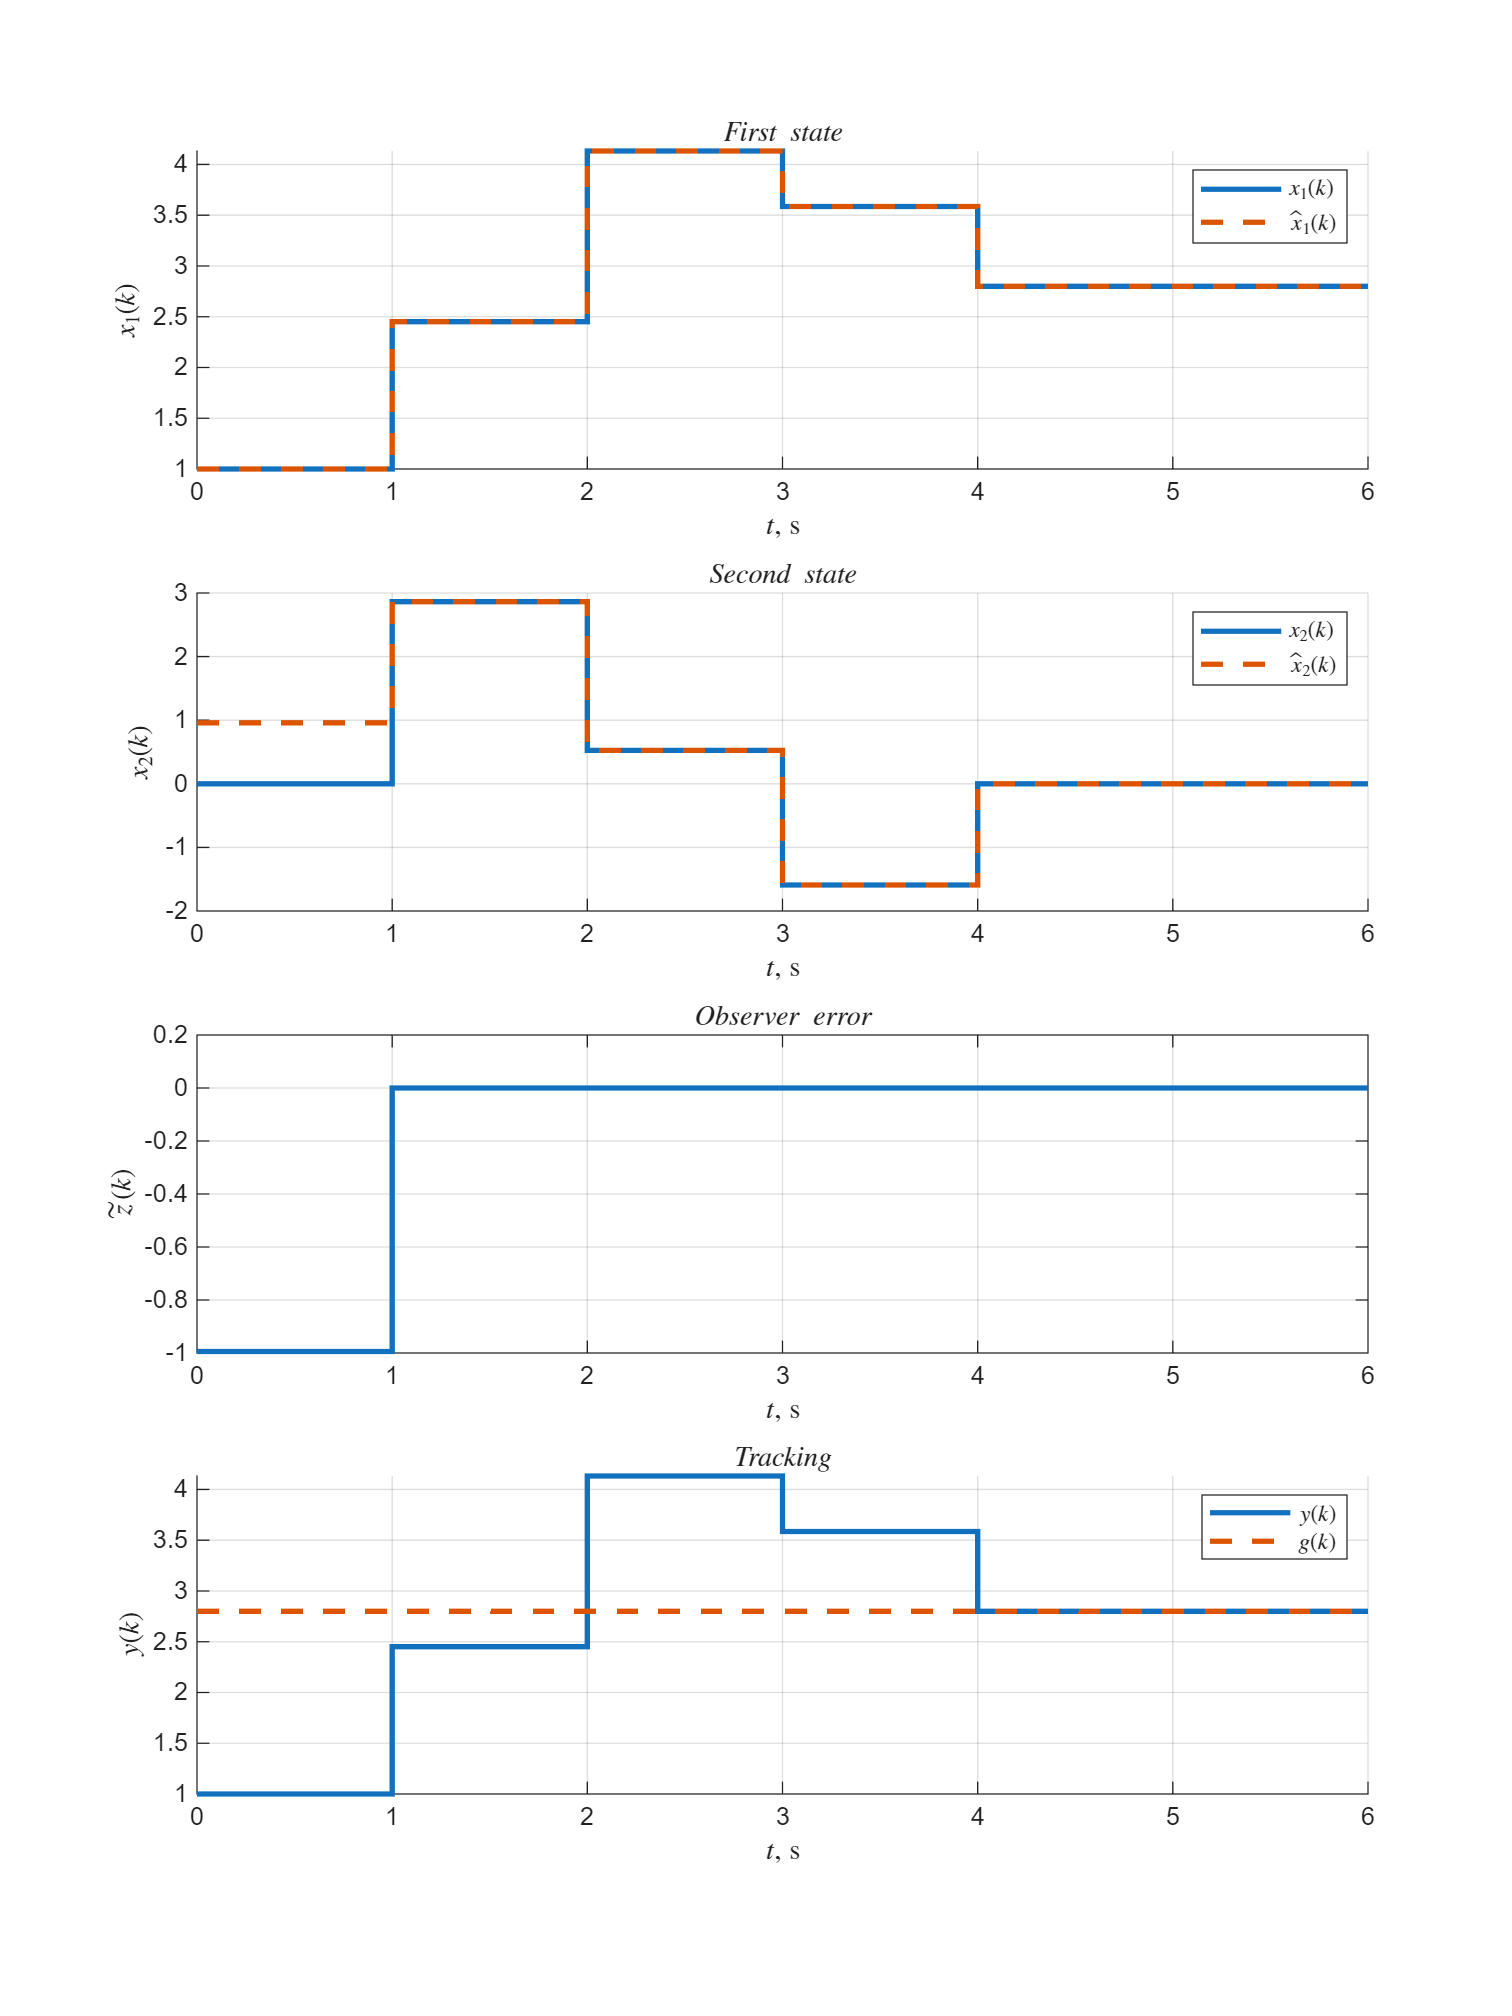



x = out.obs_tx.Data;
z = out.obs_tz.Data;
t = out.obs_tx.Time;

xh = [x(:,1) z]*R';
dz = z - x*Mn';

f = figure;
f.Position = [100 100 900 1200];

subplot(4,1,1);
hold on;
stairs(t, x(:,1), LineWidth=2);
stairs(t, xh(:,1), LineStyle="--", LineWidth=2);
hold off;

legend({"$x_1(k)$", "$\hat{x}_1(k)$"}, Interpreter="latex");
grid on;
xlim([0 6]);
title("$First\ state$", Interpreter="latex");
xlabel("$t,\;\mathrm{s}$", Interpreter="latex");
ylabel("$x_1(k)$", Interpreter="latex");

subplot(4,1,2);
hold on;
stairs(t, x(:,2), LineWidth=2);
stairs(t, xh(:,2), LineStyle="--", LineWidth=2);
hold off;

legend({"$x_2(k)$", "$\hat{x}_2(k)$"}, Interpreter="latex");
grid on;
xlim([0 6]);
title("$Second\ state$", Interpreter="latex");
xlabel("$t,\;\mathrm{s}$", Interpreter="latex");
ylabel("$x_2(k)$", Interpreter="latex");

subplot(4,1,3);
stairs(t, dz, LineWidth=2);
grid on;
xlim([0 6]);
title("$Observer\ error$", Interpreter="latex");
xlabel("$t,\;\mathrm{s}$", Interpreter="latex");
ylabel("$\tilde{z}(k)$", Interpreter="latex");

subplot(4,1,4);
hold on;
stairs(t, x(:,1), LineWidth=2);
stairs(t, 2.8*ones(size(t)), LineStyle="--", LineWidth=2);
hold off;

legend({"$y(k)$", "$g(k)$"}, Interpreter="latex");
grid on;
xlim([0 6]);
title("$Tracking$", Interpreter="latex");
xlabel("$t,\;\mathrm{s}$", Interpreter="latex");
ylabel("$y(k)$", Interpreter="latex");

exportgraphics(f, fullfile(folder, "task3_tracking_observer.png"), Resolution=600);